clear 
clc
close all

### Definition der Variablen

a = 0.0158;
b = 0.084;
c = 0.0127;
k = 11.5;

### Aufstellen der Strecke als ${\textrm{PDT}}_1$Glied

Tt = 0.2;
Kp = b/a;
T1 = 1/a;

s = tf('s');
Fs = b/(s+a)*exp(-Tt*s);

### Aufstellen der Übertragungsfunktionen für den Regler nach dem Ziegler-Nichols Verfahren

Fr = 0.9*T1/(Kp*Tt)+1/(3.33*Tt*s);

### Aufstellen des offenen und geschlossen Regelkreises

L = Fr*Fs;
T = Fr*Fs/(1+Fr*Fs);
S = 1/(1+Fr*Fs);

### Durchführen der Simulation

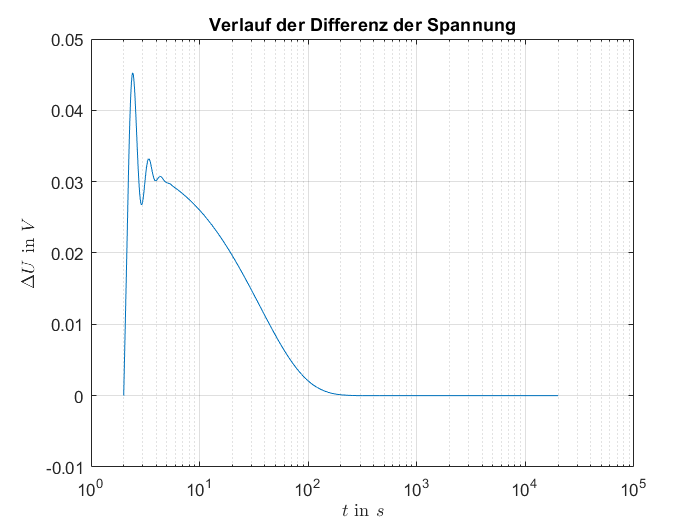

sim("windrad")
figure()
plot(U)
set(gca, 'XScale', 'log')
grid on
title("Verlauf der Differenz der Spannung")
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\Delta U$ in $V$",'Interpreter','latex')

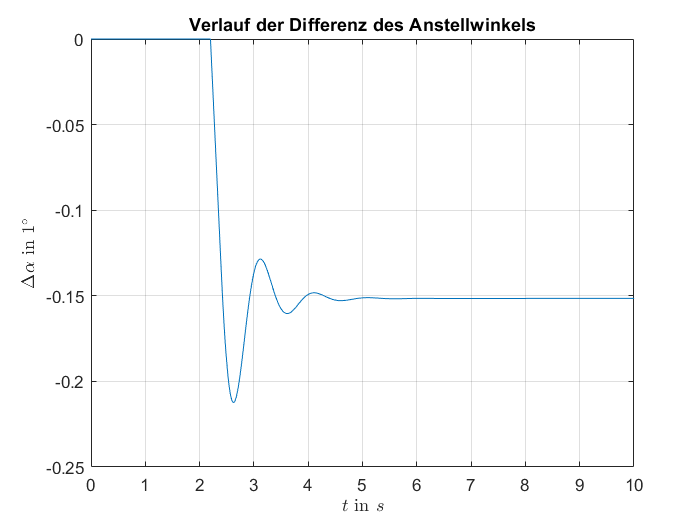

figure()
plot(alpha)
title("Verlauf der Differenz des Anstellwinkels")
xlim([0 10])
xlabel("$t$ in $s$",'Interpreter','latex')
ylabel("$\Delta  \alpha$  in  $1^{\circ}$",'Interpreter','latex')
grid on